#### Part 3

slowmotion = load("slowmotion.mat");

IQ = slowmotion.iq;
s = slowmotion.s;
sm_framerate = s.Framerate_fps;
sm_depthIncrease_iq = s.iq.DepthIncrementIQ_m;
sm_startDepth_iq = s.iq.StartDepthIQ_m;
sm_num_beams_iq = s.iq.BeamsIQ;
sm_samples_iq = s.iq.SamplesIQ;
sm_frames_iq = s.iq.FramesIQ;
tissue = slowmotion.tissue;
sm_gain_iq = s.iq.feflowgain_dB;
sm_dyn_iq = s.iq.DynRange_dB;
sm_frsig = s.iq.frsIQ_Hz;


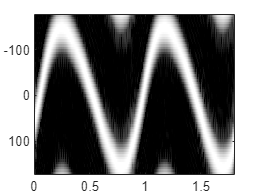

middle_beam = squeeze(IQ(:,4,:));
timeaxis=[1:s.iq.FramesIQ]/s.Framerate_fps;
depthaxis=[1:s.iq.SamplesIQ]*s.iq.DepthIncrementIQ_m*100;
%since y axis is the samples and x axis is the frames
y_axis = sm_startDepth_iq:sm_depthIncrease_iq:(sm_samples_iq-1)*sm_depthIncrease_iq + sm_startDepth_iq;
x_axis = 0:1/sm_framerate:(sm_frames_iq-1)*1/sm_framerate;
Nfft = 64;
crop = 16;
dyn = 40;
gain = -90;
depthindex = round(size(IQ,1)/2)-10:round(size(IQ,1)/2)+10;
P = zeros(Nfft, sm_frames_iq-crop+1);
for n=1:sm_frames_iq-crop+1
    iqsegm = middle_beam(depthindex,n+[0:crop-1])';
    iqsegm = iqsegm.*(hamming(crop)*ones(1,length(depthindex)));
    P(:,n) = mean(abs(fftshift(fft(iqsegm,Nfft))).^2,2);
end
freqAxis = (([0:Nfft-1]/Nfft)-0.5)*sm_framerate;
figure(), imagesc(x_axis,freqAxis,10*log10(P));
colormap(gray(255));
caxis([-dyn 0]-gain)

#### Part 4

fastmotion = load("fastmotion.mat");

IQ_fm = fastmotion.iq;
f = fastmotion.s;
fm_framerate = f.Framerate_fps;
fm_depthIncrease_iq = f.iq.DepthIncrementIQ_m;
fm_startDepth_iq = f.iq.StartDepthIQ_m;
fm_num_beams_iq = f.iq.BeamsIQ;
fm_samples_iq = f.iq.SamplesIQ;
fm_frames_iq = f.iq.FramesIQ;
fm_tissue = fastmotion.tissue;
fm_gain_iq = f.iq.feflowgain_dB;
fm_dyn_iq = f.iq.DynRange_dB;
fm_frsig = f.iq.frsIQ_Hz;

middle_beam_fm = squeeze(IQ_fm(:,4,:));
%since y axis is the samples and x axis is the frames
y_axis_fm = fm_startDepth_iq:fm_depthIncrease_iq:(fm_samples_iq-1)*fm_depthIncrease_iq + fm_startDepth_iq;
x_axis_fm = 0:1/fm_framerate:(fm_frames_iq-1)*1/fm_framerate;
timeaxis=[1:fm_frames_iq]/fm_framerate;